# DSP LAB EXPERIMENT 1

## GROUP-10 

### *KARTIKEYA KULKARNI*- B200389EC

### *S. LIKHITH* - B201299EC

1.Generate unit impulse, unit step and unit ramp

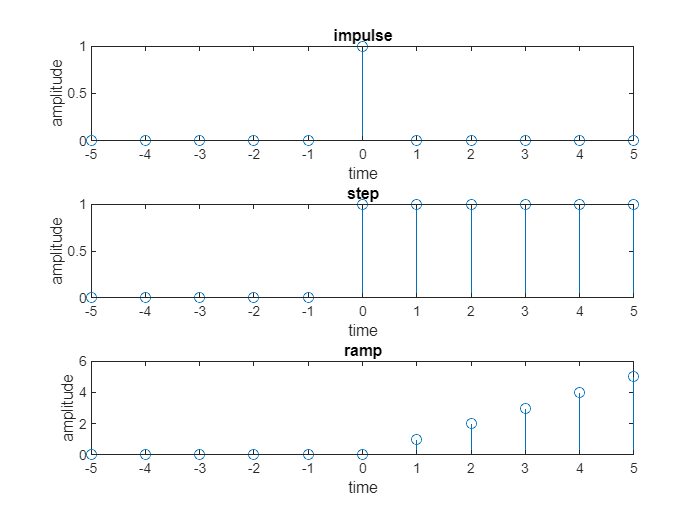

t=-5:5;
impulse=[zeros(1,5),ones(1,1),zeros(1,5)];
step=[zeros(1,5),ones(1,6)];
ramp=[zeros(1,5),0:5];
figure();
subplot(3,1,1);
stem(t,impulse);
title('impulse');
xlabel('time');
ylabel('amplitude');
subplot(3,1,2);
stem(t,step);
title('step');
xlabel('time');
ylabel('amplitude');
subplot(3,1,3);
stem(t,ramp);
title('ramp');
xlabel('time');
ylabel('amplitude');

2. Generate first few samples of the following real sequences:

a) 20(0.9)^n

b) 0.2(1.2)^n

c)(-0.8)^(n)^4

d) -4*(0.8).^n

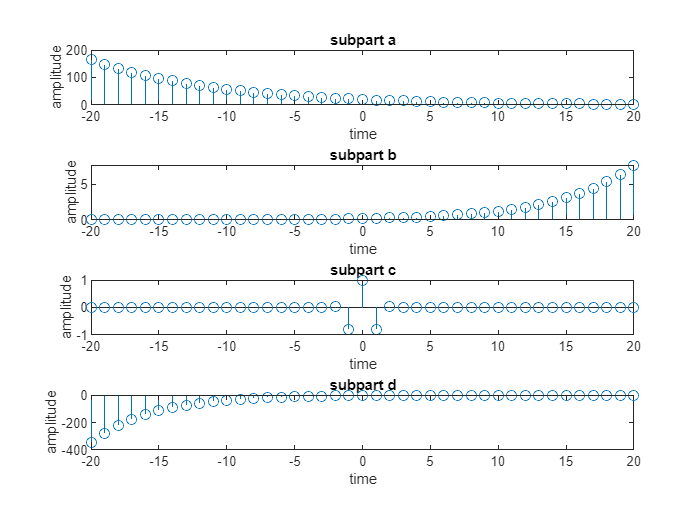

n=-20:20;
a=20*(0.9).^n;
figure();
subplot(4,1,1);
stem(n,a);
title('subpart a');
xlabel('time');
ylabel('amplitude');
% PART b
b=0.2*(1.2).^n;
subplot(4,1,2);
stem(n,b);
title('subpart b');
xlabel('time');
ylabel('amplitude');
%PART C
c=(-0.8).^(n.^4);
subplot(4,1,3);
stem(n,c);
title('subpart c');
xlabel('time');
ylabel('amplitude');
% PART D
d=-4*(0.8).^n;
subplot(4,1,4);
stem(n,d);
title('subpart d');
xlabel('time');
ylabel('amplitude');

3. Generate given complex exponential 

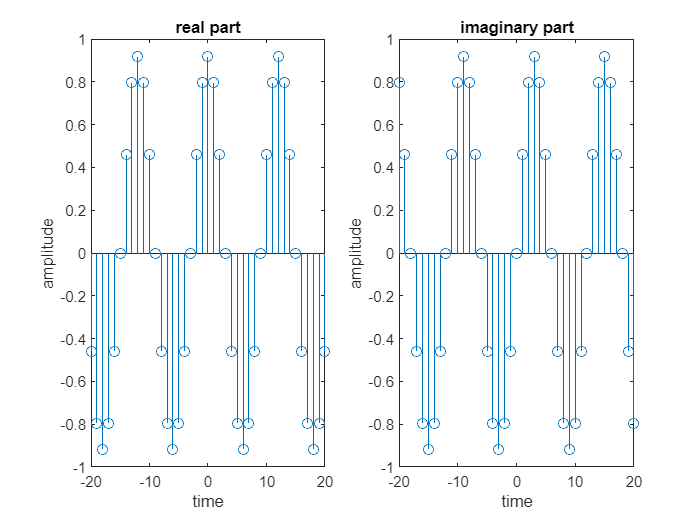

x=complex(exp(-1*(1/12)+1j*(pi/6).*n));
figure();
subplot(1,2,1);
stem (n,real(x));
title('real part');
xlabel('time');
ylabel('amplitude');
subplot(1,2,2);
stem (n,imag(x));
title('imaginary part');
xlabel('time');
ylabel('amplitude');

4. Generate the following discrete time sequences and display them

a) 

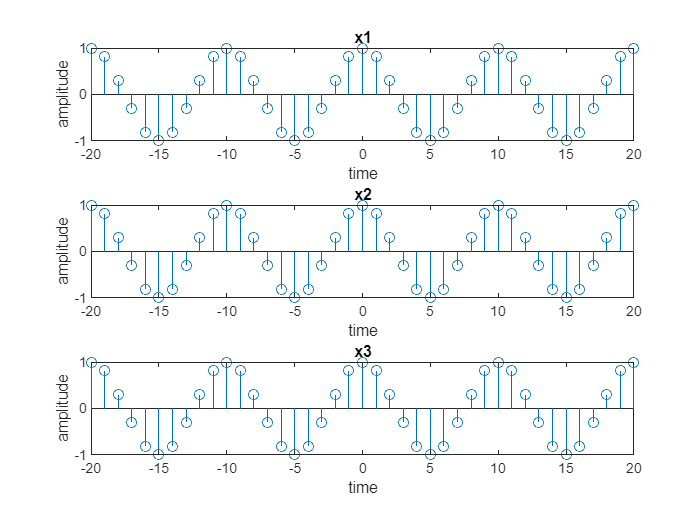

figure();
n=-20:20;
x1=cos(0.2*pi.*n);
x2=cos(1.8*pi.*n);
x3=cos(2.2*pi.*n);
subplot(3,1,1);
stem (n,x1);
title('x1');
xlabel('time');
ylabel('amplitude');
%x2
subplot(3,1,2);
stem (n,x2);
title('x2');
xlabel('time');
ylabel('amplitude');
%x3
subplot(3,1,3);
stem (n,x3);
title('x3');
xlabel('time');
ylabel('amplitude');

#### EXPLANATION:

since discrete frequencies can only lie in between 0 and 2pi, frequencies above these are just aliases of their corresponding frequencies in the (0,2pi) band.

1.8pi = 2pi - 0.2 pi

and 2.2pi = 2pi + 0.2pi

they are both aliases of 0.2pi and are therefore identical as seen in the figure.

b)

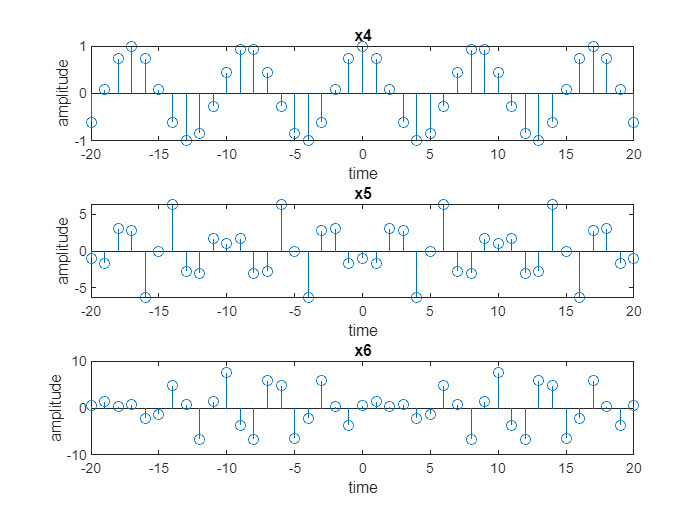

figure();
x4=cos(((4*pi)/17).*n);
x5=3*cos(1.3*pi.*n)-4*sin(0.5*pi.*n+0.5*pi);
x6=5*cos(1.5*pi.*n+0.75*pi)+4*cos(0.6*pi.*n)-sin(0.5*pi.*n);
%x4
subplot(3,1,1);
stem (n,x4);
title('x4');
xlabel('time');
ylabel('amplitude');
%x5
subplot(3,1,2);
stem (n,x5);
title('x5');
xlabel('time');
ylabel('amplitude');
%x6
subplot(3,1,3);
stem (n,x6);
title('x6');
xlabel('time');
ylabel('amplitude');

#### CALCULATIONS: 

T (x4) = [2*pi/(4*pi/17)]*N for N=2, T=17 samples

T (x5) = LCM[20, 4]=20 samples

T (x6) = LCM[4,4,10] = 20 samples

c)

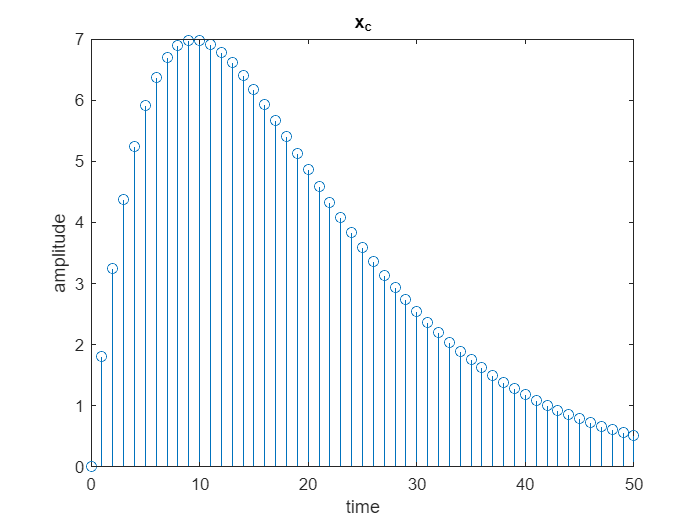

figure();
n1=0:50;
x_c=(2*(0.9).^n1).*n1;
subplot(1,1,1);
stem (n1,x_c);
title('x_c');
xlabel('time');
ylabel('amplitude');

d)

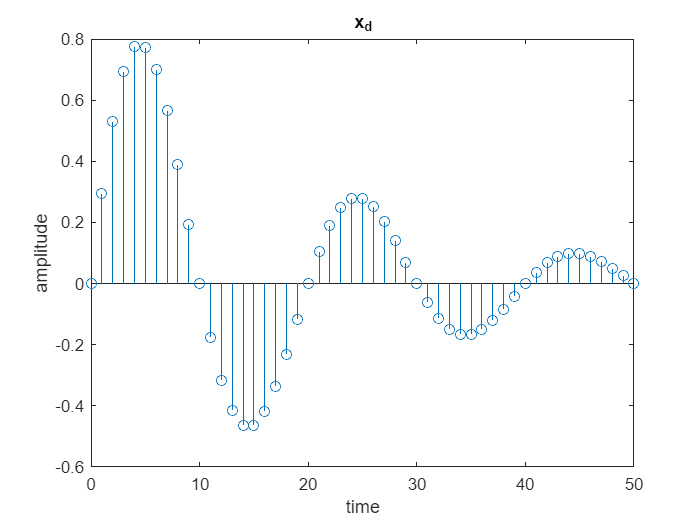

figure();
x_d=sin(0.1*pi.*n1).*((0.95).^n1);
subplot(1,1,1);
stem (n1,x_d);
title('x_d');
xlabel('time');
ylabel('amplitude');

e)

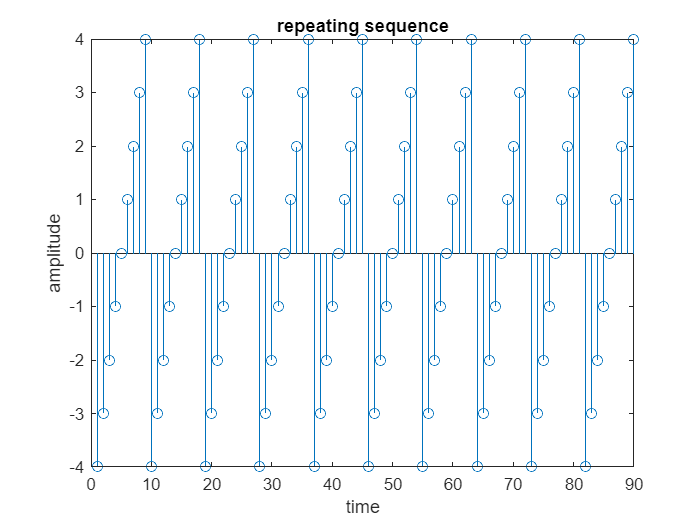

%using repmat cmd
figure();
seq_a=[-4,-3,-2,-1,0,1,2,3,4];
periodic_b=repmat(seq_a,10);
periodic_b(1,:);
stem(1:90,periodic_b(1,:));
title('repeating sequence');
xlabel('time');
ylabel('amplitude');

5. Generate and display a random signal of length 100 whose elements are uniformly distributed in the interval [-2,2]

figure();
n2=1:100;
rng(0,'twister');
a=-2;
b=2,

b = 2

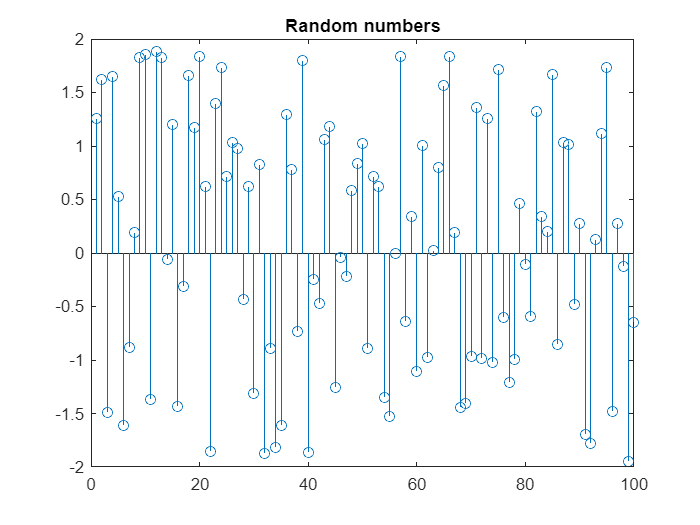

r=(b-a).*rand(1,100)+a;
subplot(1,1,1);
stem(n2,r);
title("Random numbers");

6. Generate and display a gaussian RV of length 75 whose elements are normally distributed with a zero mean and a variance of 3.

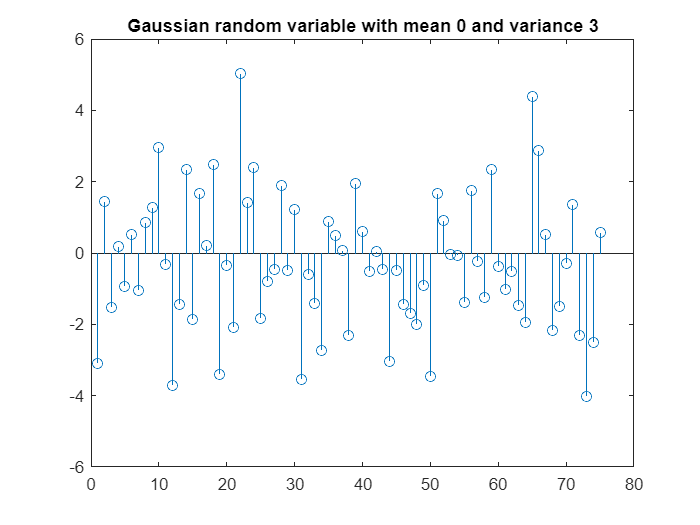

rvgauss=sqrt(3).*randn(1,75);
figure();
subplot(1,1,1);
stem(rvgauss);
title("Gaussian random variable with mean 0 and variance 3");

7. Perform convolution

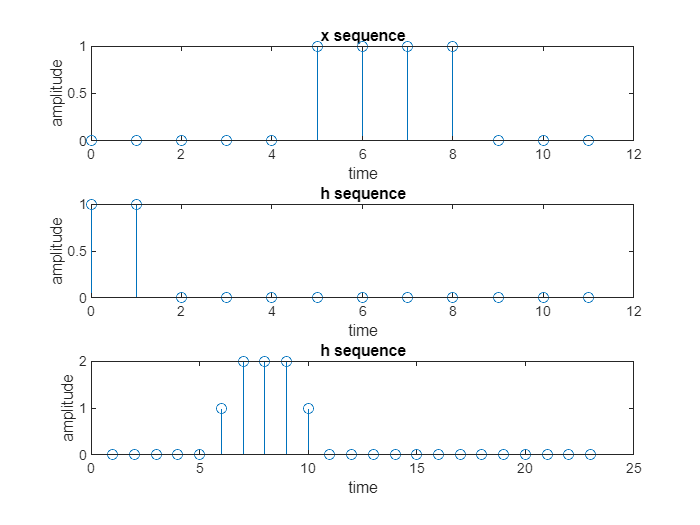

figure();
n3=0:11;
xconv=[zeros(1,5),ones(1,4),zeros(1,3)];
h=[ones(1,2),zeros(1,10)];
subplot(3,1,1);
stem(n3,xconv);
title("x sequence");
xlabel('time');
ylabel('amplitude');
subplot(3,1,2);
stem(n3,h);
title("h sequence");
xlabel('time');
ylabel('amplitude');
convans=conv(xconv,h);
subplot(3,1,3);
stem(1:23,convans);
title("h sequence");
xlabel('time');
ylabel('amplitude');

8. find step response of 0.9^n u[n]

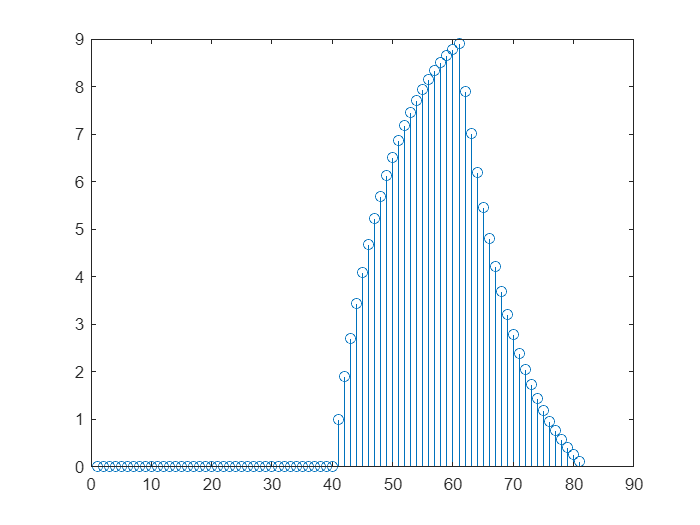

stepf=[zeros(1,20),ones(1,21)];
himpul=((0.9).^n).*stepf;
out=conv(himpul,stepf);
figure();
subplot(1,1,1);
stem(out);

title('step response q8');
xlabel('time');
ylabel('amplitude');

9. Compute convolution of x[n] = u[n]-u[n-10] and h[n] = 0.9^n u[n]

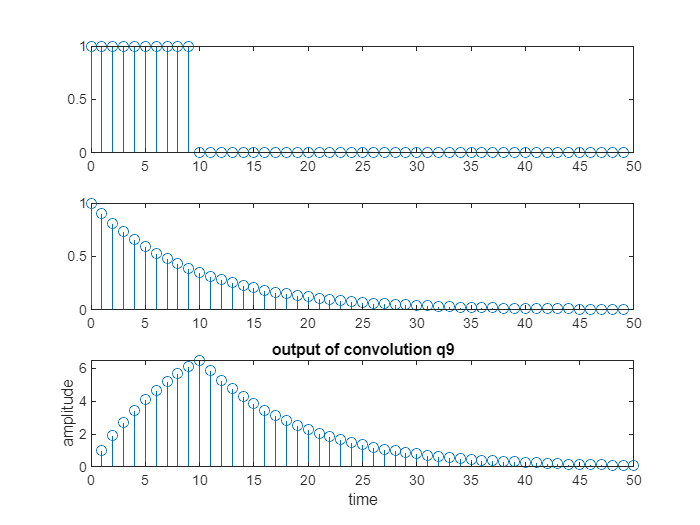

n=0:49;
u1=[ones(1,50)];
u2=[zeros(1,10),ones(1,40)];
x=u1-u2;
h_n=((0.9).^n).*u1;
y_9=conv(x,h_n);
y_9=y_9(1:50);
figure();
subplot(3,1,1);
stem(n,x);
title('u[n]');
xlabel('time');
ylabel('amplitude');
subplot(3,1,2);
stem(n,h_n);
title('h[n]');
xlabel('time');
ylabel('amplitude');
subplot(3,1,3);
stem(y_9);
title('output of convolution q9');
xlabel('time');
ylabel('amplitude');

10. compute the convolution of x=[-1 0.5]  h=[2 4 -2] using functions

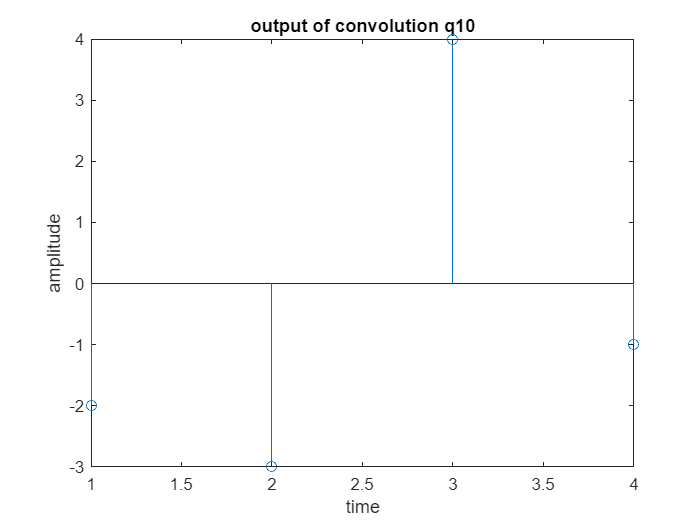

x_10=[-1 0.5];
h_10=[2 4 -2];
y_10=conv(x_10,h_10);
figure();
subplot(1,1,1);
stem(y_10);
title('output of convolution q10');
xlabel('time');
ylabel('amplitude');